# Question #5 

**>> Given**

Consider an airplane patterned after the Beechcraft Bonanza V-tailed single-engine light private airplane.  The characteristics of this airplane are as follows: aspect ratio = 6.2, wing area = 16.82 m^2 , Oswald efficiency factor = 0.91, weight = 13380 N, and zero-lift drag coefficient = 0.027.  The airplane is powered by a single piston engine capable of producing 345 hp at sea level.  Assume that the power of the engine is proportional to free-stream air density and that the two-bladed propeller has an efficiency of 0.83. 

**>> Solution**

To solve this problem we will use the function **power_cal.mlx** to calculate corresponding thrust and power value for a given velocity for 2 example aircrafts.

**>> Code**

## Preparation

ARQ5 = 6.2;
wing_areaQ5 = 16.82;
e_oQ5 = 0.91;
weightQ5 = 13380;
C_D0Q5 = 0.027;
P_max = 257266; % converted to Watts
prop_eff = 0.83;
rho_sealevelQ5 = 1.225;
rho_alt = 0.84557; % at 3.66 km

velQ5 = 20:160;

## Part (a)

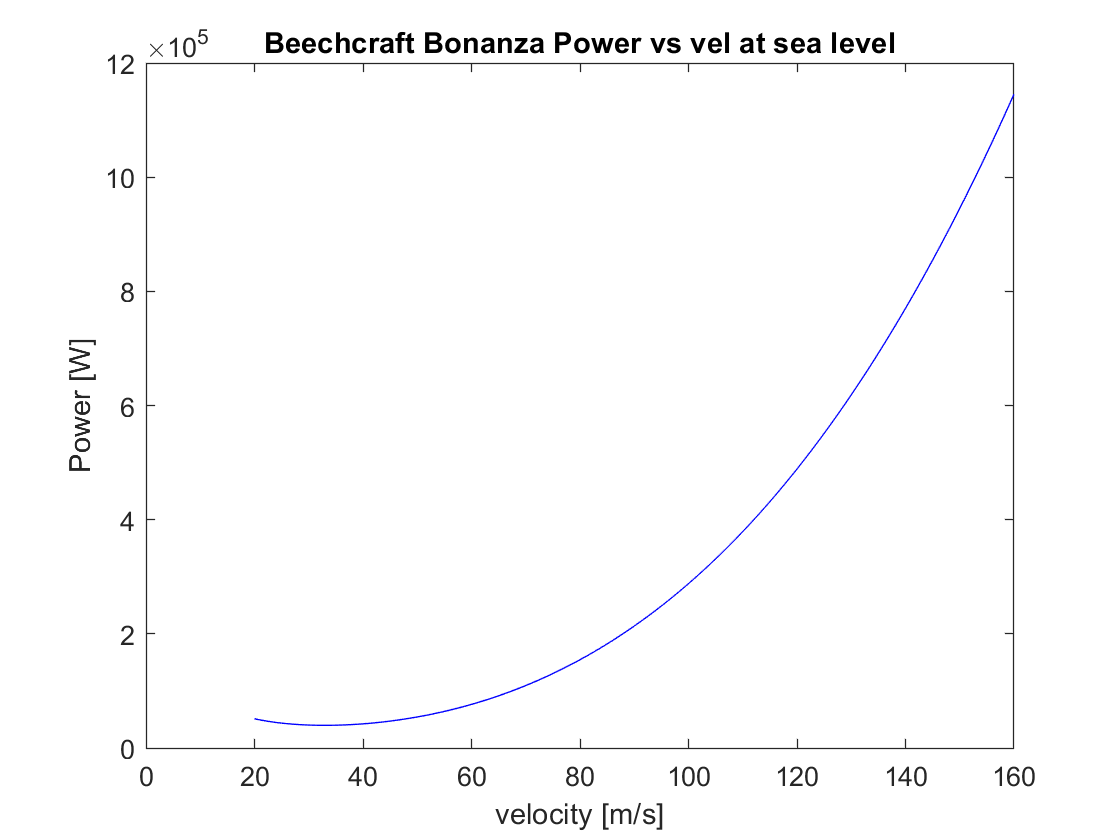

% Calculate and plot the power required at sea level as
% a function of velocity. 
[powerQ5, thrustQ5] = power_cal(rho_sealevelQ5, velQ5, wing_areaQ5, C_D0Q5, weightQ5, ARQ5, e_oQ5);
% Plot 
figure(1)
plot(velQ5, powerQ5, '-b')
xlim([0, 160])
title('Beechcraft Bonanza Power vs vel at sea level')
xlabel('velocity [m/s]')
ylabel('Power [W]')

## Part (b)

% Calculate the maximum velocity that can be achieved at sea 
% level at maximum power.
P_limit_0 = P_max * prop_eff;
syms V
a = 0.5 * rho_sealevelQ5 * wing_areaQ5 * C_D0Q5;
b = 2 * (1/e_oQ5/pi/ARQ5) * weightQ5^2 / rho_sealevelQ5 / wing_areaQ5;
eqn = round(a,4) * V^4 + round(b,1) == round(P_limit_0,1) * V;
V_max_sealevelQ5 = solve(eqn, V);

V_max_Q5b = double(max(V_max_sealevelQ5(1:2,1)));

fprintf('The maximum velocity is %f m/s', V_max_Q5b);

The maximum velocity is 89.974360 m/s

## Part (c)

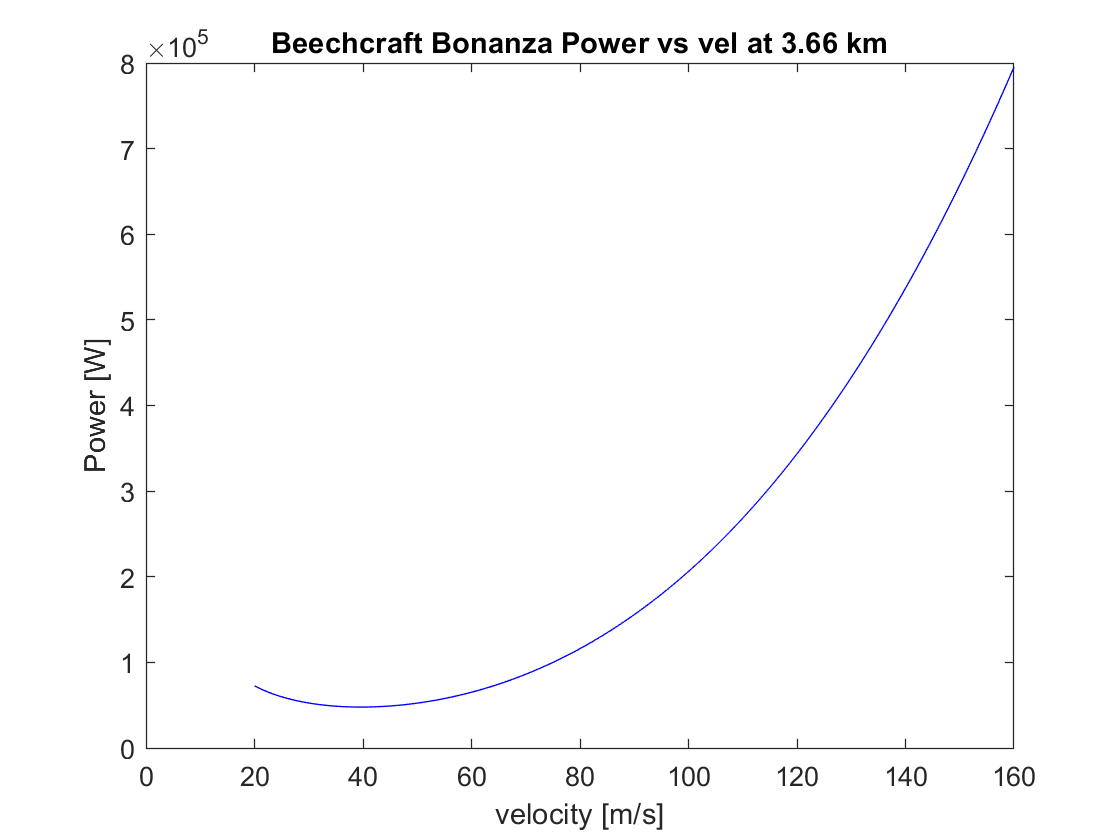

% Calculate and plot the power required at 3.66 km above sea level as a function of velocity.
[powerQ52, thrustQ52] = power_cal(rho_alt, velQ5, wing_areaQ5, C_D0Q5, weightQ5, ARQ5, e_oQ5);
% Plot 
figure(1)
plot(velQ5, powerQ52, '-b')
xlim([0, 160])
title('Beechcraft Bonanza Power vs vel at 3.66 km')
xlabel('velocity [m/s]')
ylabel('Power [W]')

## Part (d)

P_limit_02 = (rho_alt / rho_sealevelQ5 * P_max) * prop_eff;
syms V
a = 0.5 * rho_sealevelQ5 * wing_areaQ5 * C_D0Q5;
b = 2 * (1/e_oQ5/pi/ARQ5) * weightQ5^2 / rho_sealevelQ5 / wing_areaQ5;
eqn = round(a,4) * V^4 + round(b,1) == round(P_limit_02,1) * V;
V_max_sealevelQ52 = solve(eqn, V);

V_max_Q5d = double(max(V_max_sealevelQ52(1:2,1)));

fprintf('The maximum velocity is %f m/s', V_max_Q5d);

The maximum velocity is 78.565648 m/s